# Identificación del sistema: Respuesta al escalón.

SIMULACION: Se realiza el ensayo al escalón, de subida y de bajada, y se importan los datos:

datos_simulacion = readmatrix('datosV2.DAT');
t = datos_simulacion(:,1) - 3.006216984;
output = datos_simulacion(:,2) - min(datos_simulacion(:,2));
input = datos_simulacion(:,3)*(3/5);

Ts = mean(diff(t));

% Filtrado de los datos

% Datos de entrada:
% t
% input
% output

% Datos filtrados:
% Tt
% entrada
% salida

start_time = 0; 
end_time = 6;     
intervalo = 0.001; 

n = 1;  % MATLAB indexa desde 1
num_points = floor((end_time - start_time) / intervalo);

for i = 1:num_points
    % avanzar hasta que t(n) supere el límite del intervalo actual
    while (n < length(t)) && (t(n) < (i * intervalo + start_time))
        n = n + 1;
    end

    Tt(i) = (i - 1) * intervalo;
    entrada(i) = input(n);
    salida(i) = output(n);
end

entrada(1) = 0;
data_id = iddata(salida', entrada', intervalo);


datos_medidos = readtable('datos_reales.csv');

t_medida = (datos_medidos.Var4(4:end) + 3); % Offset del tiempo, el medido arranca en los negativos
%t_medida = t_medida(3:end);

Tm = mean(diff(t_medida))

Tm = 2.0000e-04

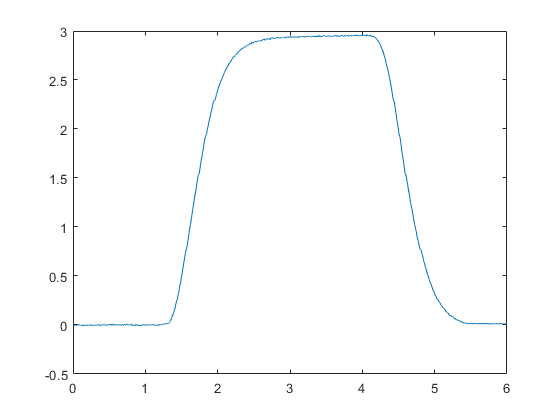


y_medida = datos_medidos.Var5(4:end);
%y_medida = y_medida(3:end);

y_medida = y_medida - mean((y_medida(1:6000)));


fs = 1/Tm;        % frecuencia de muestreo (Hz)
fc = 50;          % frecuencia de corte del pasabajos (Hz)
[b, a] = butter(4, fc/(fs/2));  % filtro Butterworth de orden 4

y_medida = filter(b, a, y_medida);  % aplicar filtro
plot(t_medida,y_medida);



u_medida = datos_medidos.Var6(4:end);
%u_medida = u_medida(3:end);

u_medida(u_medida < 4) = 0; %
u_medida(u_medida >= 4) = 3;

data_id_escalon = iddata(y_medida, u_medida, Tm);

s = tf('s');
G_ideal = 1/(s*0.1 + 1)^6;



TEST PBRS

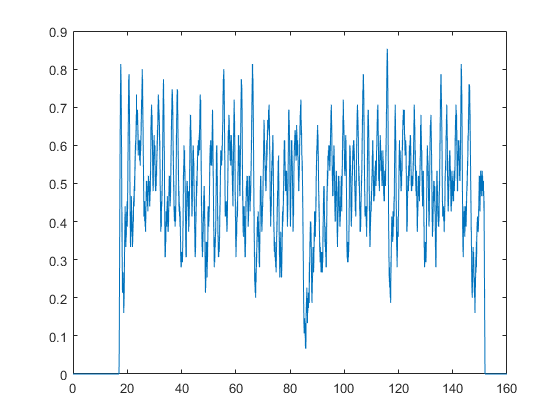

datos_medidos_prbs = readtable('1.csv');

%t_medida_prbs = (datos_medidos_prbs.Var4(4:end) + 3); % Offset del tiempo, el medido arranca en los negativos
%t_medida = t_medida(3:end);

Tm_prbs = 1/200;

y_medida_prbs = datos_medidos_prbs.Var2;
y_medida_prbs = (y_medida_prbs-1000)/3000;

for i=1:length(y_medida_prbs)
    if (y_medida_prbs(i)<0)
        y_medida_prbs(i) = 0;
    end
end

%y_medida = y_medida(3:end);

%y_medida_prbs = y_medida_prbs - mean((y_medida_prbs(1:6000)));


fs = 1/Tm_prbs;        % frecuencia de muestreo (Hz)
fc = 50;          % frecuencia de corte del pasabajos (Hz)
[b, a] = butter(4, fc/(fs/2));  % filtro Butterworth de orden 4

%y_medida_prbs = filter(b, a, y_medida_prbs);  % aplicar filtro
%plot(t_medida,y_medida_prbs);


u_medida_prbs = datos_medidos_prbs.Var1;

u_medida_prbs(u_medida_prbs < 2500) = 0; %
u_medida_prbs(u_medida_prbs >= 2500) = 1;
plot((0:Tm_prbs:(length(y_medida_prbs)-1)*Tm_prbs),y_medida_prbs);

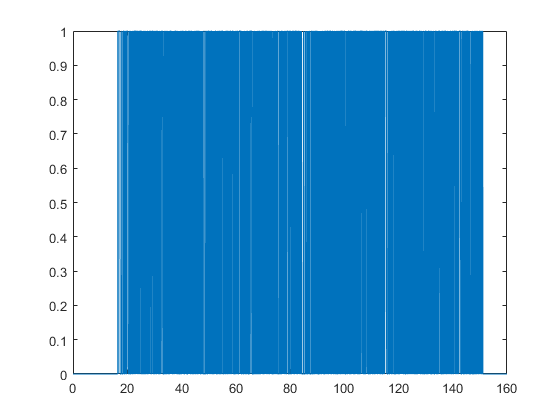


plot((0:Tm_prbs:(length(y_medida_prbs)-1)*Tm_prbs),u_medida_prbs);

data_id_prbs = iddata(y_medida_prbs, u_medida_prbs, Tm_prbs);

## Diseño de PID